Torque area - Falde tryk

clear
clf

% A = 1593 * 2; %mm^2
r_outer = [0.054 0.034 0.030]

r_outer =         0.054        0.034         0.03


A_current = 512 * 2 %mm^2 % 512

A_current =         1024


T = [10e3 1e3 0.1e3];
S = T./r_outer / A_current

S =        180.84       28.722       3.2552



n_y = 2; %Sikkerheds factor
S_y = 375; %375 - 460 % edu pack C45 - AISI 1040
S_max =  S_y / n_y

S_max =         187.5


syms A_sym

A_min_eq = S_max == T(1)/r_outer(1) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol =        493.83


A_min_eq = S_max == T(2)/r_outer(2) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol =        78.431


A_min_eq = S_max == T(3)/r_outer(3) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol =        8.8889


Aksel for dimentionering

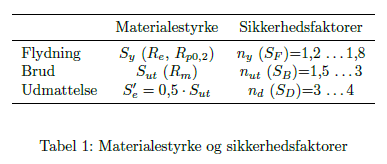

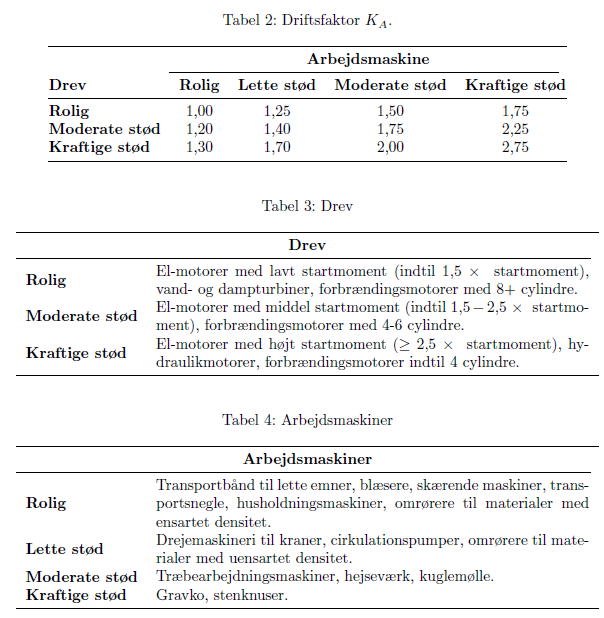

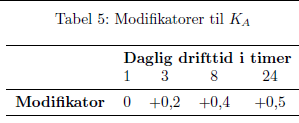

 at yield

For solid shaft

% K_a = 1.0; % tabel 2,3,4 and 5 in "Fordimensionering af aksler"
T_max = [10e3 10e3 1e3 0.1e3];% * K_a; %Nm

% d = 95e-3; %mm
n_y = 2; %drev Kraftige stød % arbejds maskinen Lette stød
S_y = 1100; %375 - 460 % edu pack C45 - AISI 1040

% tau_max_Pa = T_max / (pi/16 * d^3) 
% ta_max_MPa = tau_max_Pa/1e6
tau_til = 1/sqrt(3) * S_y / n_y

tau_til =        317.54



d_m = (T_max / (pi/16  * tau_til * 1e6)).^(1/3)

d_m =      0.054332     0.054332     0.025219     0.011705


d_mm = d_m * 1000

d_mm =        54.332       54.332       25.219       11.705


For hollow shaft

d = [88e-3 42e-3 30e-3 20e-3] ; % inner diameter
D_sol = zeros(1, length(T_max)); % stand ind for outer diameter
for i = 1:length(T_max)
    syms D
    W_p = pi * (D^4 - d(i)^4)/(16*D); %MMTH page 46 
    D_eq = tau_til*1e6 == T_max(i) / W_p; % setting up equation
    
    D_sol = solve(D_eq, D); %solving for outer diameter
    D_sols(i) = double(D_sol(4));
end

D_sols

D_sols =      0.093026     0.059677     0.034134     0.020977


D_sols_mm = D_sols *1e3

D_sols_mm =        93.026       59.677       34.134       20.977


Tightning force

format shortg
f_s = 0.18; %friction of steel on steel
F_pre = [58.57e3 58.57e3 13.866e3 13.866e3 4.357e3] * 2 * f_s %N % pretension on two bolts % 5.8

F_pre =         21085        21085       4991.8       4991.8       1568.5


F_pre = [146.8e3 * 2 146.8e3 * 2 34.757e3 34.757e3 4.357e3] * 2 * f_s %N % pretension on two bolts % 10.9

F_pre =     1.057e+05    1.057e+05        12513        12513       1568.5


%https://bolte.dk/cylinderhovedet-insexskrue-iso-4762-zinkflake-behandlet-flznl-480h-staal-kl-109-m10x30-200-stk
F_pre = [171.8e3 171.8e3 40.673e3 40.673e3 4.357e3] * 2 * f_s %N % pretension on two bolts % 12.9

F_pre =         61848        61848        14642        14642       1568.5


% https://bolte.dk/cylinderhovedet-insexskrue-iso-4762-ubehandlet-staal-kl-129-m10x30-200-stk

% M20 M10 M6
d_shaft = [95e-3 65e-3 60e-3 42e-3 60e-3 ];
T_max = [10e3 5.1e3 1e3 473 100];
F_max = T_max ./ d_shaft

F_max =    1.0526e+05        78462        16667        11262       1666.7


Springers

d_shaft_dim = 48;
d_hub = 1.8*d_shaft_dim

d_hub =          86.4


A_pressure_bolt = 97.6; %mm^2
F_pre(3)/A_pressure_bolt

ans =        150.02



A_pressure_bolt = 326.7; %mm^2
F_pre(1)/A_pressure_bolt

ans =        189.31


S_y = 1100;
A_t = [245 84.3 58 20.1];
d = [0.020 0.012 0.010 0.006]; % * u.mm; % spindeldiameteren
p = [0.0025 0.00175 0.0015 0.001]; % * u.mm; %pitch (afstand fra top til top)
A_r = [225 76.3 52.3 17.9] * (1/1000)^2; %areal fra roddiameter se table 8-1 i shigleys eller one note
d_r = sqrt(4 * A_r / pi);% rod diameteren
d_m = (d + d_r)/2;      %middeldiameter
d_p = (d + d_r)/2;      % Pitch diameter
D_Km = d * 1.3          % mean bearing diameter at the nut or at the bolt head springer side 534
l = p
lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
f = 0.18; %friktionskoefficienten i gevind
fc = 0.18; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel

d_c_min = 0.010%0.011 %* u.mm; %mindste diameter på spændeskive
d_c_max = d_c_min * 1.5%0.016 %* u.mm; %største diameter på spændeskive

d_c =  (d_c_min + d_c_max) / 2;%middel diameter på spændeskive

n_bolts = 2; % number of bolts

% F_pre = [171.8e3 171.8e3 40.673e3 40.673e3 4.357e3] * 2 * f_s %N % pretension on two bolts % 12.9
% F_i = [171.8e3, 40.673e3, 4.357e3]
% F_i = 40e3 %/ n_bolts

S_p = 0.85 * S_y
F_p = S_p * A_t
F_i = 0.70 * F_p %/ n_bolts% nonperm

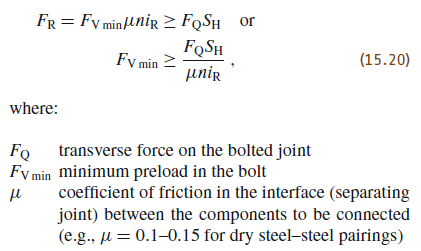

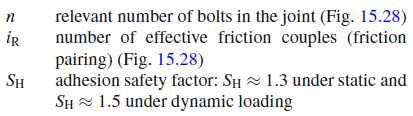

$F_A$ - additionally loaded by an axial working load 

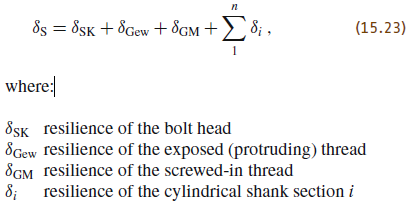

l_SK = d * 0.4; %for hexagon socket head cap screws (bolts),
E_s = 207e9;   % young modulus for the bolt for stål 207 GPa E-modul
delta_SK = 4 * l_SK/(E_s * pi * d)

l_Gew = 0.017; % length of the protruding thread (not engaged)
delta_Gew = 4 * l_Gew / (E_s * pi * d_r)

E_M = E_s; % young modulus for the nut/hole
l_G = 0.5 * d_r % as a rule page 529. 10mm is half.
delta_G = 4 * l_G / (E_s * pi * d_r)

l_M = 0.33 * d % as a rule page 529.
delta_M = 4 * l_M / (E_M * pi * d)

delta_GM = delta_G + delta_M

l_1 = 0; % full threaded
d_1 = 0; % full threaded
delta_i = 4 * l_1 / (E_s * pi * d1) % add one for each diameter size

delta_S = delta_SK + delta_Gew + delta_GM + delta_i


% delta_V_P = 

% delta_H_P = 

w = 2; % joint coeffecient; 2 for screw-in joints, 1 for through-bolted joints

% delta_P = 2/w * delta_V_P + delta_H_P
f_Z = (3 + 3)*1e-6 % surface roughness 10-40

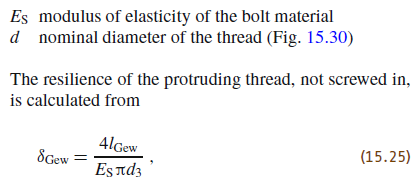

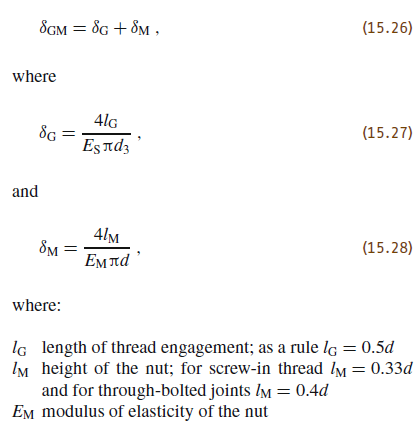

The resiliences of the individual shank areas

(15.32)

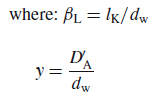

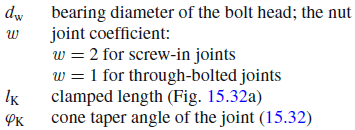

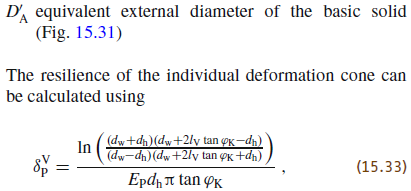

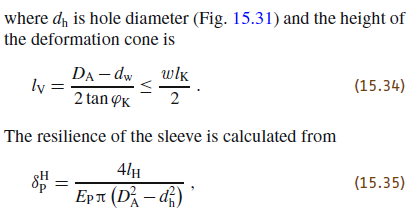

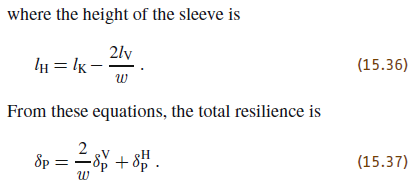

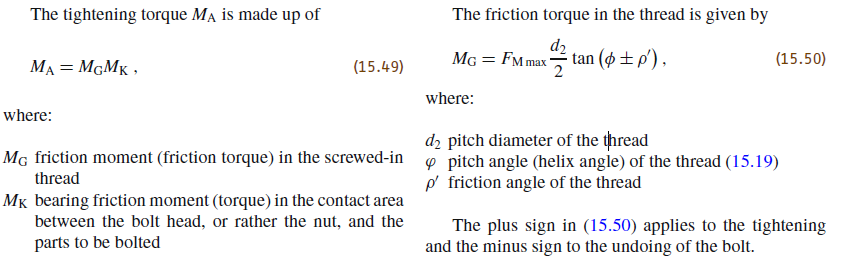

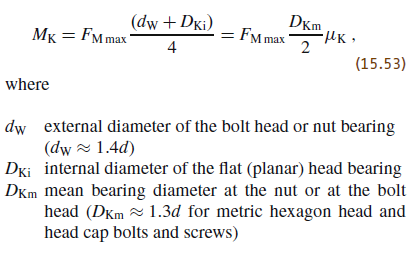

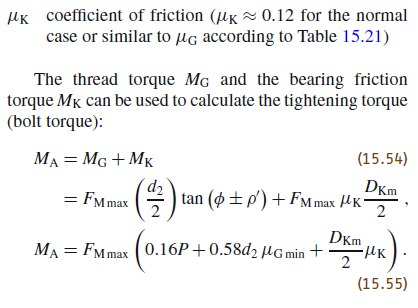

Med springer

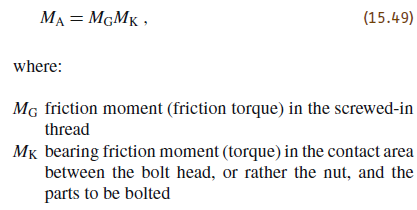

F_Z = 0; % The resulting loss of force is called the loss of preload
F_Mmin = F_i + F_Z

F_Mmin =    1.6035e+05        55174        37961        13155


alpha_A = 1.6% tightening factor % Table 15.19: Tightening with torque wrench

alpha_A =           1.6


F_Mmax = alpha_A * F_Mmin % 

F_Mmax =    2.5656e+05        88279        60738        21049


mu_G_min = 0.12; % Table 15.21 dry black tempered / steel blank
mu_K = 0.12; % for the normal case or similar to mu_G according to Table 15.21
M_A = F_Mmax .* (0.16*p + 0.58*d_p * mu_G_min + D_Km/2 * mu_K)

M_A =        832.55       174.49       100.34        21.11


Med shigleys

%funktion for forspændingsmomentet
T_for = (F_i .* d_m/2) * ((tan(lambda) + f * secd(alpha)) ./...
    (1 - f * tan(lambda) * secd(alpha))) + (F_i * fc * d_c)/2

T_for =        561.24       139.64       87.047       23.916


% T_ = vpa(unitConvert(T, u.N * u.m), 4)
% T_bolt = T_for / n_bolts

d_shaft = [95e-3 48e-3 60e-3 60e-3]; 
F_i_fric = F_i * 2 * 2 * f

F_i_fric =    1.1545e+05        39726        27332       9471.9


T_max = [10e3 473 1e3 100];
F_max = T_max ./ d_shaft

F_max =    1.0526e+05       9854.2        16667       1666.7



F_i_max = F_max / n_bolts;
T_max = (F_i_max .* d_m/2) * ((tan(lambda) + f * secd(alpha)) ./...
    (1 - f * tan(lambda) * secd(alpha))) + (F_i_max * fc * d_c)/2

T_max =        184.21       12.469       19.109        1.515


% I_p = pi*d.^4 / 32
% tau_max = T_for .* d ./ (I_p * 2)

% tau_max = T_for * 16 ./ (pi * d.^3)
d_r

d_r =      0.016926    0.0098564    0.0081603     0.004774


tau_max = 1100e6

tau_max =       1.1e+09


T_max_calc = tau_max / 16 * (pi * d_r.^3)

T_max_calc =        1047.3       206.81       117.37         23.5


Spline

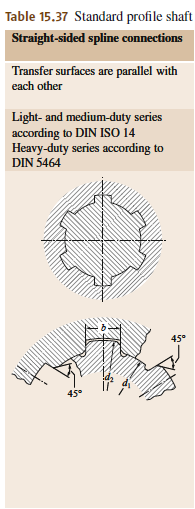Springers

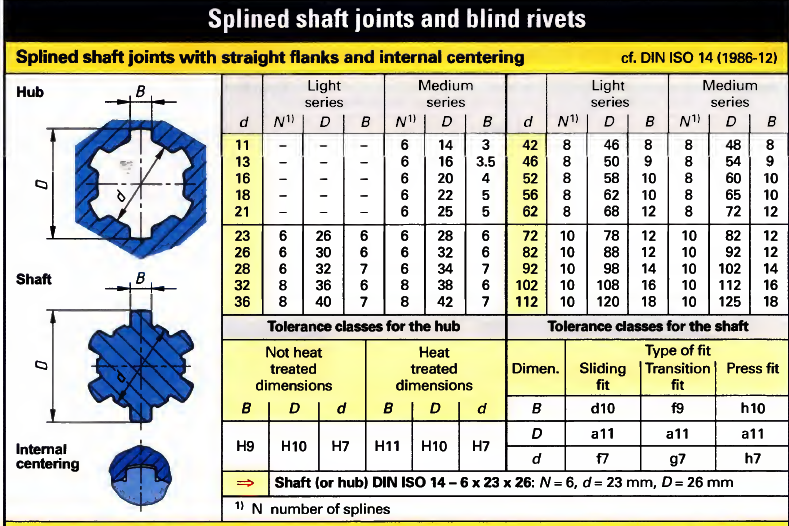MMTH

T_max = [10e3 1e3];
d = [82e-3 42e-3]; % d>77,8 see above %shaft diameter
N = [10 8]; %number of theeth
% D = 92e-3; %medium series outer diameter
D = [88e-3 46e-3]; %light series outer diameter
B = [12 8]; %width of tooth

L = [50e-3 25e-3];%length of spline interacion
r = (D./2 - (D-d)./2)

r =         0.041        0.021


F = T_max ./ r

F =     2.439e+05        47619


A = (D-d)./2 .* L %areal i kontakt pr spline

A =       0.00015        5e-05


S_Pa = F ./ (A .* N)

S_Pa =     1.626e+08   1.1905e+08


S_MPA =S_Pa /1e6

S_MPA =         162.6       119.05


Spline holds on Light series

DIN 5480-16 2006

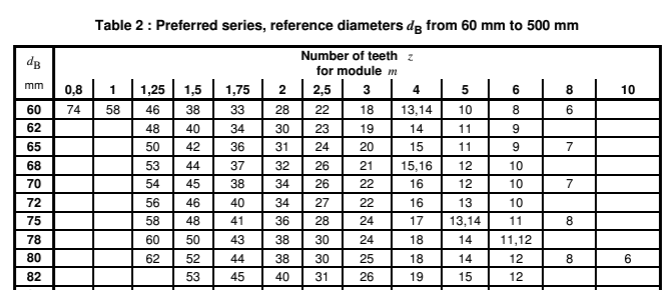

% d_B

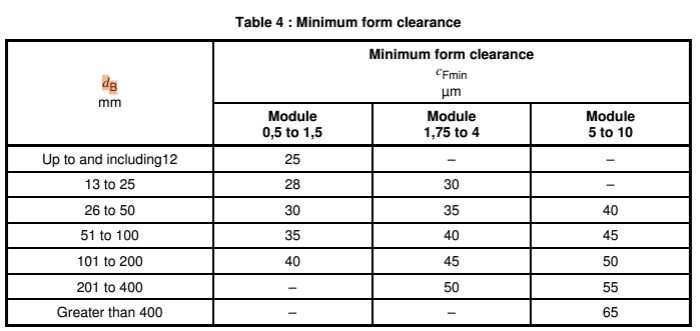

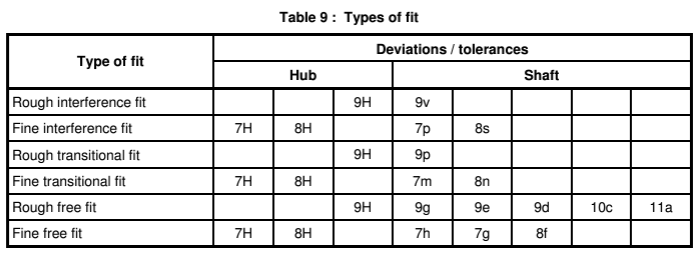

shaft 9e

hub 9H

se side 103 i den blå

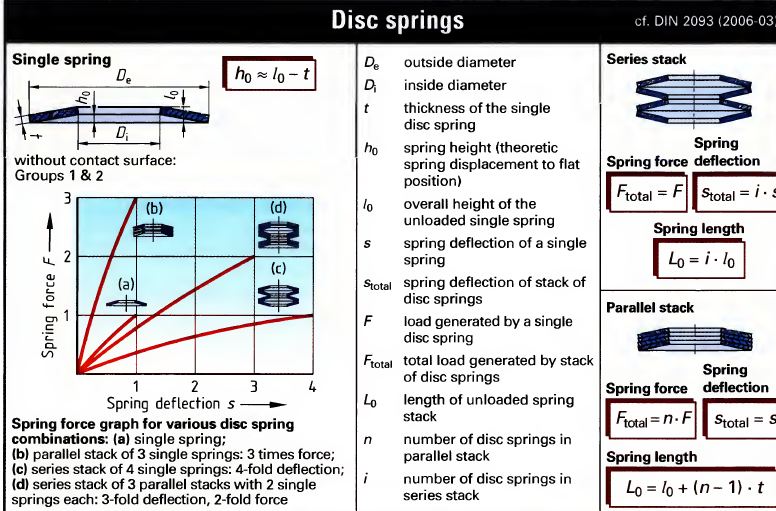

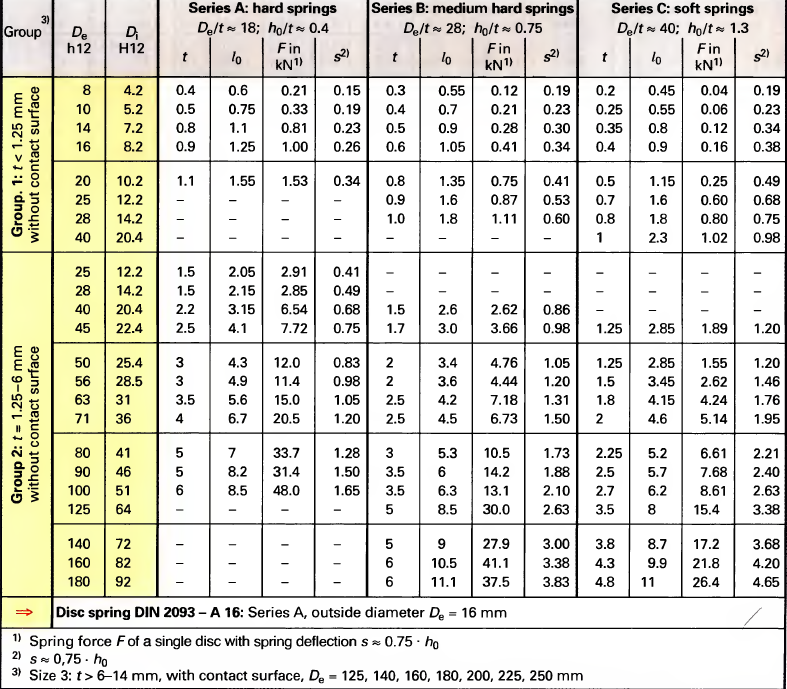

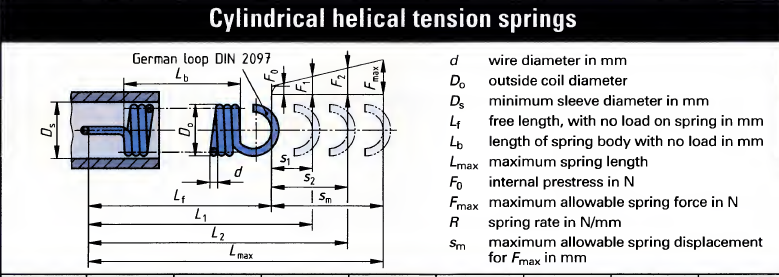

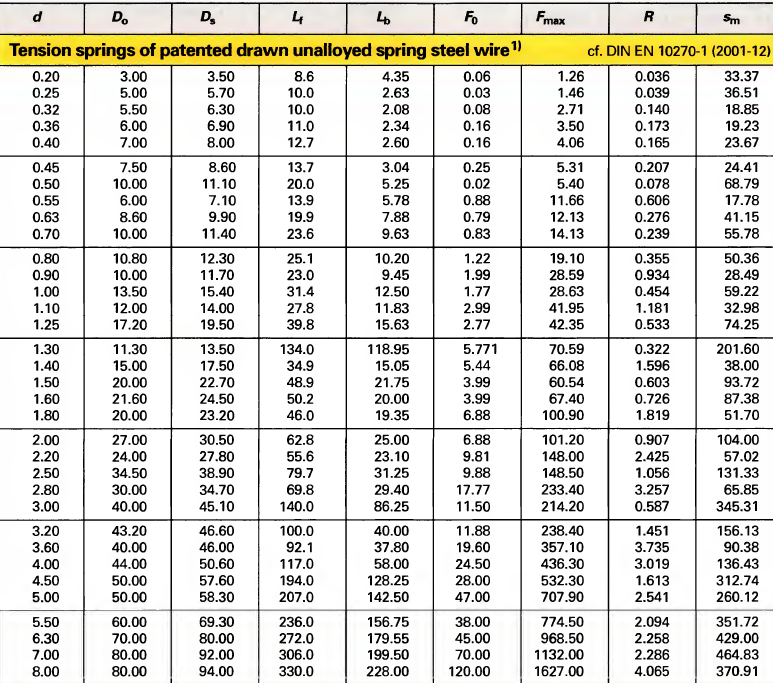

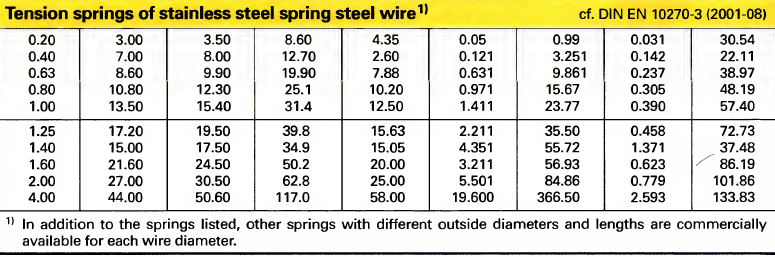

## Spring energi calculations

**Assumptions:**

- Frictionless rotor

- Frictionless push on rotor

- The equivalence principle

- Linear spring konstant

100 Nm tranducer

**Motor**

clear

r =         0.023


clf
theta_release = 9; %rotation for release
r = 0.070/2 - 0.012 % fixed radius % radius where the force is apllied
%this is also the approximate middle point of the friction

I = 0.0012; %HMA4 80 1-2
% I = 0.0057;HMA4 90S-6
% I = 0.1617; %HMA4 160L-6
% I = 0.335; % HMC4 225M-2 % possible for 120hz 


T =           1.2


%compression of spring if not fully
% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring

F_to_store =        52.174


T = 1.2 % minimum torque for 120 Hz 2 pole FS 71, 0.7 for non overload
% T = 96 % HMC4 225M-2 at 120 Hz 
F_to_store = T / r % how much torque i needed to store energi in the spring


s_spring_max =         0.002


**Radial spring data**

% C07200630620M % 	fri længde=	15,75 max vandring = 6,96 De=18,29 Di =15,09

k_spring =         9110


% max kraft 62,28
s_spring_max = 2e-3 % Max compression if depends on allowed clearance (measure) 
k_spring = 9.11e3% spring constant

s_spring_push =     0.0028636



% T / r = k_spring * s_spring_max % equation for spring coefficient
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

if s_spring_max > s_spring_push
    s_spring_max = s_spring_push

s_spring_max =         0.002


else

F_spring =         36.44


    s_spring_max
end
F_spring = k_spring * s_spring_max * 2

**Axial spring**

f_k = 0.15; %kinetic friction coeffecient for steel vs steel \cite MMTH
k_axial = 0.57e3; % N/mm --> N/m % max kraft 41,87, max vandring 66,80, total lenth 123,95 L0 = 57,15

F_axial =         31.35


% E08500632250S % varenummer trækfjeder SODEMANN

F_fric =        4.7025


x_axial = 55e-3; % udspændt fjeder til træk af claw
F_axial = k_axial * x_axial
F_fric = F_axial * f_k

**Energi**

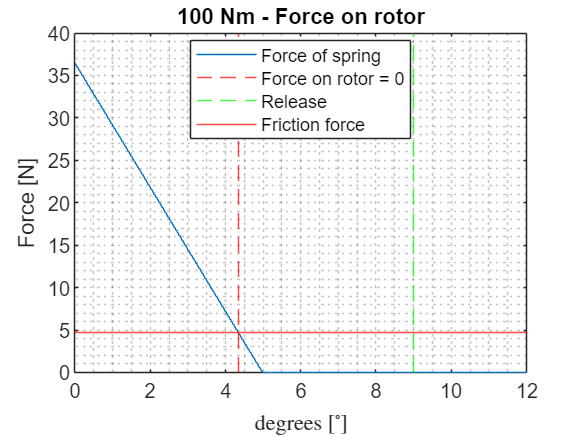

thetas = 0:0.05:12; % angle traveled
syms omega s_spring_sym

for i = 1:length(thetas)
    x = 2*pi*r * thetas(i)/360; % travel on the circle

    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations 
        % spring push distance
    else
        s_spring = s_spring_max;
    end
    
    % finding the force on the rotor
    F_spring(i) = k_spring * (s_spring_max - s_spring) * 2; %two spring sides
    F_spring_eq = k_spring * (s_spring_max - s_spring_sym) * 2; %two spring sides

    % finding the energi
    W_spring_eq = int(F_spring_eq, s_spring_sym, 0, s_spring);
    W_spring = double(W_spring_eq); 

    if W_spring > 0
        % W_spring
    else
        W_spring = 0;
    end
    W_fric = F_fric * x;
    W_total(i) = W_spring - W_fric; 

    % calculating the angular speed
    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total);
theta_spring_max = thetas(max_index); % holder for max spring

plot(thetas, F_spring, DisplayName="Force of spring")
hold on
xline(theta_spring_max, 'r--', DisplayName='Force on rotor = 0')
xline(theta_release, 'g--', DisplayName='Release')
yline(F_fric, 'r', DisplayName="Friction force")
ylabel("Force [N]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

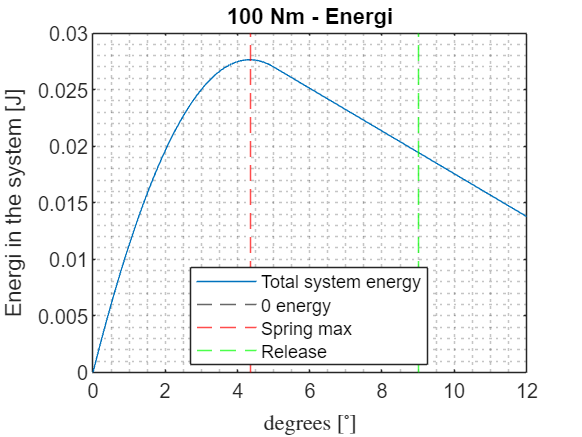

legend(Location="best")
title("100 Nm - Force on rotor")
hold off

plot(thetas, W_total, DisplayName="Total system energy")
hold on
yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

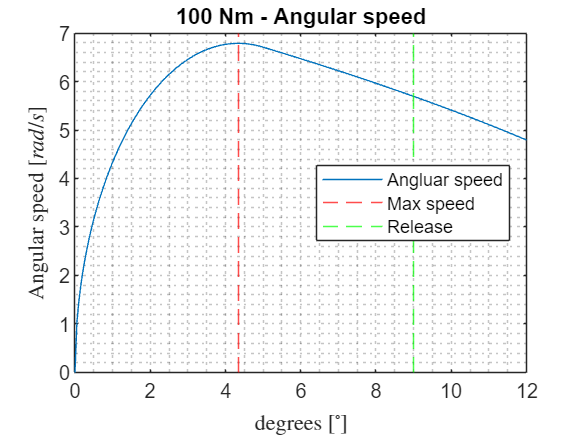

legend(Location="best")
title("100 Nm - Energi")
hold off

plot(thetas, omega_sol2, DisplayName="Angluar speed")
hold on
xline(theta_spring_max, 'r--', DisplayName='Max speed')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

legend(Location="best")
title("100 Nm - Angular speed")
hold off

1 kNm tranducer

**Motor data**

clear

r =         0.034


clf
theta_release = 9; %rotation for release
r = 0.092/2 - 0.012 % fixed radius % radius where the force is apllied
%this is also the approximate middle point of the friction

I =  0.0095; % HMA4 112M-2
% I = 0.1617; %HMA4 160L-6
% I = 0.335; % HMC4 225M-2
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 5.7105; % HMC4 315L2-6


T =    102


%compression of spring if not fully
% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring

F_to_store =         3000


T = 102 % minimum torque for 10 Hz 2 pole FS 112
% T = 934 % minimum torque for 120 Hz 6 pole FS 315 (HMC4 315L2-6)
F_to_store = T / r % how much torque i needed to store energi in the spring

P_fr = 454.43;

**Radial spring data**

n_stack_para = 1; %number of paralel stacked disc springs for more force
% (stacked same way)
n_stack_series = 2; %number of series stacked disc springs for more force
% (stacked opposite way)

k_spring =       553000


F_realese = 553 * n_stack_para; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s_spring_max = 0.5e-3 * n_stack_series; %(0.53e-3)
k_spring = F_realese / s_spring_max

s_spring_push =     0.0027125



% T / r = k_spring * s_spring_max
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

if s_spring_max > s_spring_push
    s_spring_max = s_spring_push

s_spring_max =         0.001


else

F_spring =         1106


    s_spring_max
end
F_spring = k_spring * s_spring_max * 2 % two radial springs

**Axial spring**

f_k = 0.15; %kinetic friction coeffecient for steel vs steel \cite MMTH
k_axial = 1.77e3; % N/mm --> N/m % max kraft 137,09, max vandring 70,36, total lenth 159,26 L0 = 	88,90
% E07500853500M % varenummer trækfjeder SODEMANN
%49,3
% x_axial = 49.3e-3;%65e-3; % udspændt fjeder til træk af claw
% F_axial = k_axial * x_axial
% F_fric = F_axial * f_k

f_k = 0.15; %kinetic friction coeffecient for steel vs steel \cite MMTH
k_axial = 0.57e3; % N/mm --> N/m % max kraft 41,87, max vandring 66,80, total lenth 123,95 L0 = 57,15

F_axial =         31.35


% E08500632250S % varenummer trækfjeder SODEMANN

F_fric =        4.7025


x_axial = 55e-3; % udspændt fjeder til træk af claw
F_axial = k_axial * x_axial
F_fric = F_axial * f_k

**Energi**

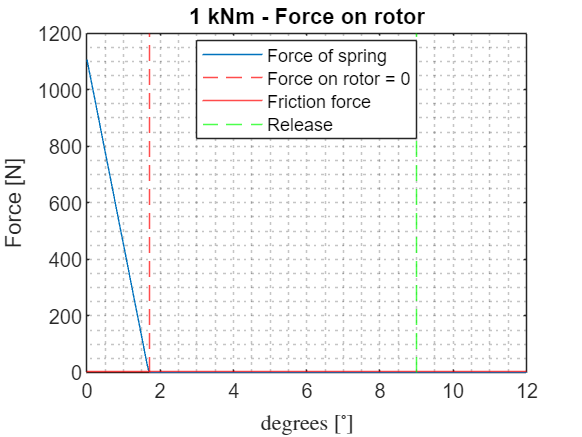

thetas = 0:0.05:12; % angle traveled
syms omega s_spring_sym

for i = 1:length(thetas)
    x = 2*pi*r * thetas(i)/360; % travel on the circle

    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations 
        % spring push distance
    else
        s_spring = s_spring_max;
    end
    
    % finding the force on the rotor
    F_spring(i) = k_spring * (s_spring_max - s_spring) * 2; %two spring sides
    F_spring_eq = k_spring * (s_spring_max - s_spring_sym) * 2; %two spring sides

    % finding the energi
    W_spring_eq = int(F_spring_eq, s_spring_sym, 0, s_spring);
    W_spring = double(W_spring_eq); 

    if W_spring > 0
        % W_spring
    else
        W_spring = 0;
    end
    W_fric = F_fric * x;
    W_total(i) = W_spring - W_fric; 

    % calculating the angular speed
    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total);
theta_spring_max = thetas(max_index); % holder for max spring

plot(thetas, F_spring, DisplayName="Force of spring")
hold on
xline(theta_spring_max, 'r--', DisplayName='Force on rotor = 0')
yline(F_fric, 'r', DisplayName="Friction force")
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Force [N]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

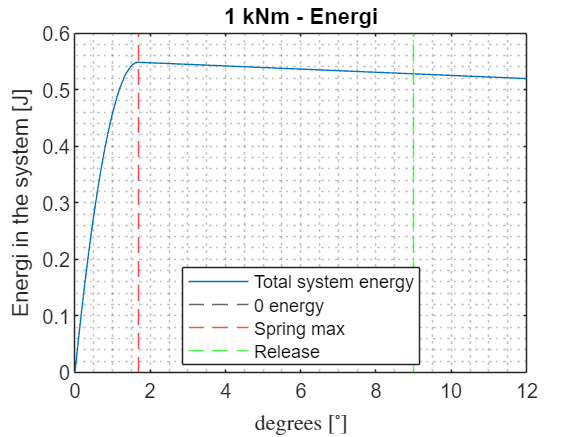

legend(Location="best")
title("1 kNm - Force on rotor")
hold off

plot(thetas, W_total, DisplayName="Total system energy")
hold on
yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

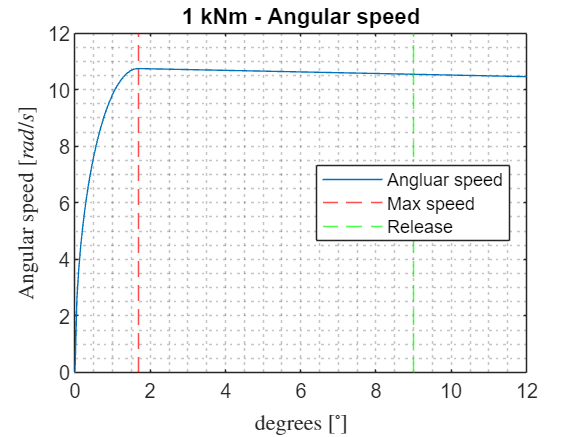

legend(Location="best")
title("1 kNm - Energi")
hold off

plot(thetas, omega_sol2, DisplayName="Angluar speed")
hold on
xline(theta_spring_max, 'r--', DisplayName='Max speed')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

legend(Location="best")
title("1 kNm - Angular speed")
hold off

10 kNm tranducer

Radial spring data

**Motor data**

clear

r =         0.054


clf
theta_release = 9; %rotation for release
r = 0.132/2 - 0.012 % fixed radius % radius where the force is apllied
%this is also the approximate middle point of the friction

% I = 0.2554; % HMC4 180L-6
% I = 0.335; % HMC4 225M-2
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-6
I = 15.9356; % inertia of the test motor % HMC3 355L-6

%compression of spring if not fully

T =         8149


% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring

F_to_store =    1.5091e+05


% T = 1121 % minimum torque for 10 Hz 4 pole FS 180
T = 8149 % minimum torque for 120 Hz 6 pole FS 400
F_to_store = T / r % how much torque i needed to store energi in the spring

**Radial spring data**

n_stack_para = 1; %number of paralel stacked disc springs for more force
% (stacked same way)
n_stack_series = 2; %number of series stacked disc springs for more force
% (stacked opposite way)

k_spring =       553000


F_realese = 553 * n_stack_para; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s_spring_max = 0.5e-3 * n_stack_series; %(0.53e-3)
k_spring = F_realese / s_spring_max

s_spring_push =       0.13644



% T / r = k_spring * s_spring_max
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

if s_spring_max > s_spring_push
    s_spring_max = s_spring_push

s_spring_max =         0.001


else

F_spring =         1106


    s_spring_max
end
F_spring = k_spring * s_spring_max * 2
% A = 283.5 * 2 % test of surface presure on spring buffer
% S = F_spring / A - OK

**Axial spring**

f_k = 0.15; %kinetic friction coeffecient for steel vs steel \cite MMTH
k_axial = 1.77e3; % N/mm --> N/m % max kraft 137,09, max vandring 70,36, total lenth 159,26 L0 = 	88,90

F_axial =        115.05


% E07500853500M % varenummer trækfjeder SODEMANN

F_fric =        17.258


x_axial = 65e-3; % udspændt fjeder til træk af claw
F_axial = k_axial * x_axial
F_fric = F_axial * f_k

**Energi**

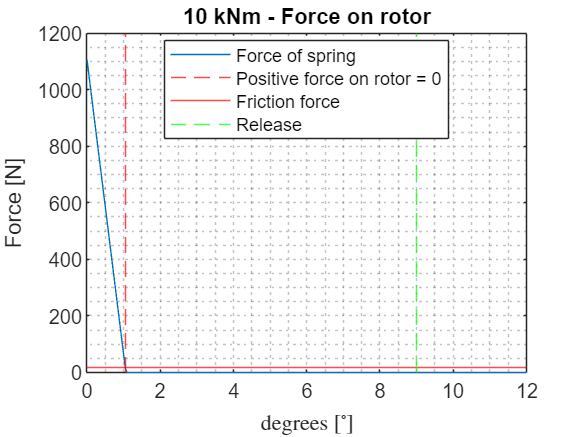

thetas = 0:0.05:12; % angle traveled
syms omega s_spring_sym

for i = 1:length(thetas)
    x = 2*pi*r * thetas(i)/360; % travel on the circle

    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations 
        % spring push distance
    else
        s_spring = s_spring_max;
    end
    
    % finding the force on the rotor
    F_spring(i) = k_spring * (s_spring_max - s_spring) * 2; %two spring sides
    F_spring_eq = k_spring * (s_spring_max - s_spring_sym) * 2; %two spring sides

    % finding the energi
    W_spring_eq = int(F_spring_eq, s_spring_sym, 0, s_spring);
    W_spring = double(W_spring_eq); 

    if W_spring > 0
        % W_spring
    else
        W_spring = 0;
    end
    W_fric = F_fric * x;
    W_total(i) = W_spring - W_fric; 

    % calculating the angular speed
    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total);
theta_spring_max = thetas(max_index); % holder for max spring

plot(thetas, F_spring, DisplayName="Force of spring")
hold on
xline(theta_spring_max, 'r--', DisplayName='Positive force on rotor = 0')
yline(F_fric, 'r', DisplayName="Friction force")
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Force [N]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

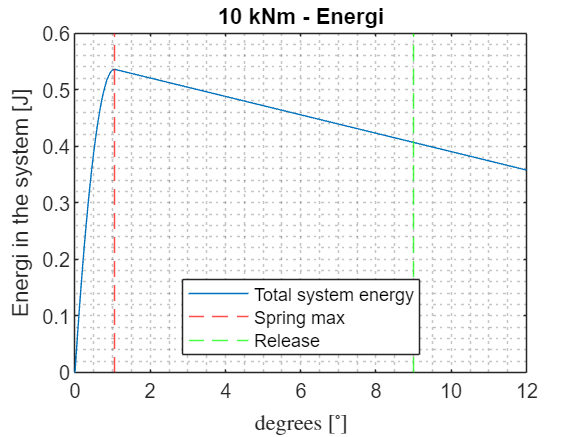

legend(Location="best")
title("10 kNm - Force on rotor")
hold off

plot(thetas, W_total, DisplayName="Total system energy")
hold on
% yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

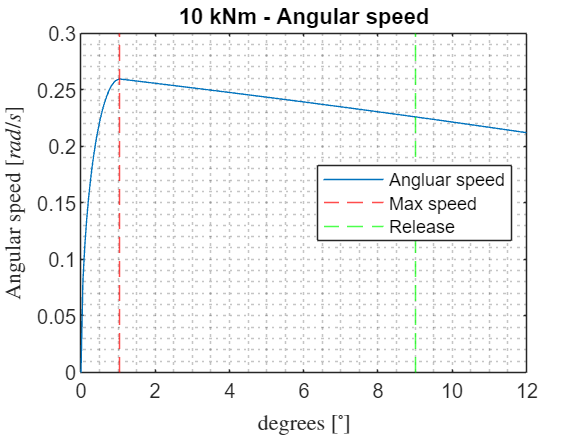

legend(Location="best")
title("10 kNm - Energi")
hold off

plot(thetas, omega_sol2, DisplayName="Angluar speed")
hold on
xline(theta_spring_max, 'r--', DisplayName='Max speed')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")

legend(Location="best")
title("10 kNm - Angular speed")
hold off